clc
clear all
close all

**Checking max Disp and Force in Exp Values**

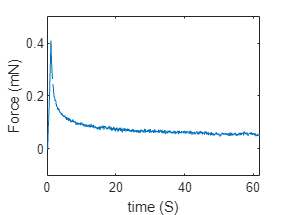

Expdata= xlsread('C:\Users\kondiboyina.v\Documents\Vineel\Nano-Indentation Results\Axolotl15cm\Timepoint2\011R_TP2\Fast\P_1.xlsx');
figure
plot(Expdata(:,1),Expdata(:,3)*10)%factor of 10 converts gf to mN
% Remove rows with NaN values
Expdata = Expdata(~any(isnan(Expdata), 2), :);
sizeExp= length(Expdata(:,3));
xlabel('time (S)');
ylabel('Force (mN)');

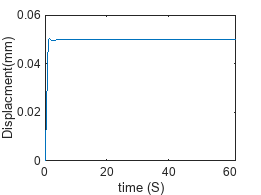

figure
plot(Expdata(:,1),Expdata(:,2))
xlabel('time (S)');
ylabel('Displacment(mm)');

% [MaxDisp,n]= max(Expdata(:,2));
% MaxTime= Expdata(n,1)

MaxTime = 1.2500

% MaxDisp

MaxDisp = 0.0502

% MaxForce_Exp= max(Expdata(:,3))*10 %factor of 10 converts gf to mN

MaxForce_Exp = 0.4094

% EqForce_Exp= mean(Expdata(sizeExp-200:sizeExp,3)*10)

EqForce_Exp = 0.0537

**Plotting Exp and Fit**

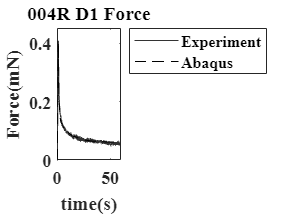

ID=4;
a=1;
figure1=figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(Expdata(:,1),Expdata(:,3)*10, '-', 'linewidth',0.2, 'Color',[0.2 0.2 0.2])
hold on
%for fileID=a:a  
     AbaqusFit_Filename=sprintf('011R_Fast_D1_VEonly.xlsx');
    Abaqusdata= xlsread(AbaqusFit_Filename);
    plot(Abaqusdata(:,1),Abaqusdata(:,2)*-1000,'--k', 'linewidth',0.4)
    hold on
%end
hold off
legend('Experiment', 'Abaqus', 'location', 'bestoutside','orientation','vertical')
xlabel('time(s)')
ylabel('Force(mN)')
titleg=sprintf('00%dR D%d Force',ID,a);
title(titleg);
xlim([0 60])
ylim([0 0.45])
box(axes1,'on');
% Set the remaining axes prorerties
set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
    'FontSize',12,'FontWeight','bold');

figure2=figure

figure2 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


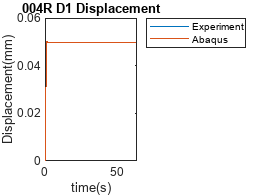

plot(Expdata(:,1),Expdata(:,2))
hold on
plot(Abaqusdata(:,1),Abaqusdata(:,4)*-1)
hold off
legend('Experiment', 'Abaqus', 'location', 'bestoutside','orientation','vertical')
xlabel('time(s)')
ylabel('Displacement(mm)')
titleg=sprintf('00%dR D%d Displacement',ID,a);
title(titleg);    

AbaqusFit_Image=sprintf('00%dR_C_D%d_RealDisp_slow.jpg',ID,a);
saveas(figure1,AbaqusFit_Image)  % here you save the figure

## Error

% size_VE= length(Abaqusdata(:,2));
% Maxforce_VE= max(Abaqusdata(:,2)*-1000)

Maxforce_VE = 0.4106

% EqForce_VE = mean(Abaqusdata(size_VE,2)*-1000)

EqForce_VE = 0.0606

% pcError_pkForce= (MaxForce_Exp-Maxforce_VE)/MaxForce_Exp*100

pcError_pkForce = -0.2997

% pcError_EqForce= (EqForce_Exp-EqForce_VE)/EqForce_Exp*100

pcError_EqForce = -12.7076